data_all = {};
for recID = [3,6,9,12,19]

clearvars -except data_all recID


ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

%% 240207
% recID = 3;
%% 240208
% recID = 6;
%% 240209_1
% recID = 9;
%% 240210_1
% recID = 12;
%% 240212
% recID = 19;

% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

cd(rootdir)

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
dataTypes = 's'; % data types to be loaded
spikeData = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
% [Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData,'include','all');

% Global Figure directory
GbFigDir = 'F:\Data\GroupForaging\Analysis\figure';

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
unit_ids = spikeData.good_units.cluster_id;
regions = cell(length(unit_ids),1);
for unit = 1:length(unit_ids)
    unit_id = unit_ids(unit);
    depth = spikeData.good_units.depth(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    regions{unit} = region;
end
spikeData.good_units.region = regions;



## Extract waveforms

path_recdir = fullfile(ephysDir,bname_ephys,'Processed');
waveData = getSpikeWaveforms(path_recdir,probeNum);


% Add spike features
[waveData.waveforms.region] = spikeData.good_units.region{:};
n_unit = spikeData.numGoodUnits;
for unit = 1:n_unit
    spikeData.good_units.trough2peak(unit) = waveData.waveforms(unit).troughtoPeak;
end
spikeData.good_units.celltype = cell(n_unit,1);
spikeData.good_units.celltype(spikeData.good_units.trough2peak <= 0.33) = {'Interneuron'};
spikeData.good_units.celltype(spikeData.good_units.trough2peak > 0.33) = {'Excitatory'};



% Cell type classification based on physiological features
target_units = strcmp(spikeData.good_units.region,'MEC');
n_mec = sum(target_units);
% target_units = 1:spikeData.numGoodUnits;
trough2peak = [spikeData.good_units.trough2peak]; trough2peak = trough2peak(target_units);
unit_depth = [spikeData.good_units.depth]; unit_depth = unit_depth(target_units);
unit_fr = [spikeData.good_units.fr]; unit_fr = unit_fr(target_units);
celltype = [spikeData.good_units.celltype]; celltype = celltype(target_units);


### Social modulation

file_path = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Social_modulation_240210_1.xlsx';
opts = detectImportOptions(file_path);
opts = setvartype(opts, 'RecDate', 'string');
opts = setvartype(opts, 'Animal','string');
T_social = readtable(file_path,opts);

idx = strcmp(T_social.RecDate,recName) & strcmp(T_social.Animal,bname_ephys);
self_land = T_social.self_land(idx);
self_toff = T_social.self_toff(idx);
other_land = T_social.other_land(idx);
other_toff = T_social.other_toff(idx);

new_data = [repmat({recName},[n_mec,1]),num2cell(unit_fr),num2cell(unit_depth),celltype,num2cell(trough2peak),num2cell(self_land),num2cell(self_toff),num2cell(other_land),num2cell(other_toff)];
data_all = [data_all; new_data];
end

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240207 ...
Loading spike data ...
Kilosort outputs found
Manual curation found


Kilosort outputs found.
Manual curation found


Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240208 ...
Loading spike data ...
Kilosort outputs found
Manual curation found


Kilosort outputs found.
Manual curation found


Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240209_1 ...
Loading spike data ...
Kilosort outputs found
Manual curation found


Kilosort outputs found.
Manual curation found


Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240210_1 ...
Loading spike data ...
Kilosort outputs found
Manual curation found


Kilosort outputs found.
Manual curation found


Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240212 ...
Loading spike data ...
Kilosort outputs found
Manual curation found


Kilosort outputs found.
Manual curation found


### FIGURE

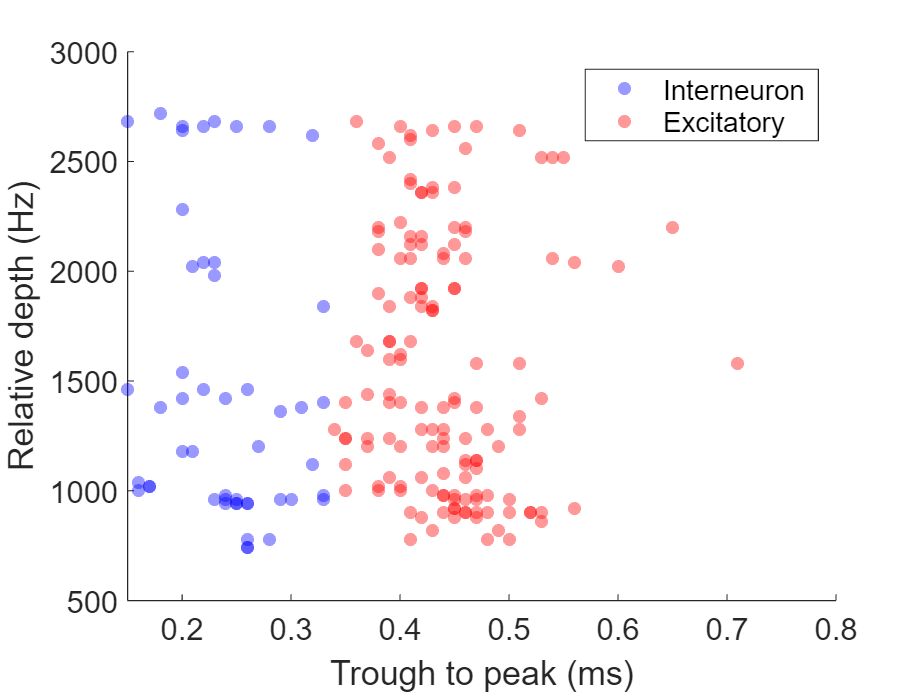

celltype = data_all(:,4);
trough2peak = cell2mat(data_all(:,5));
unit_depth = cell2mat(data_all(:,3));
unit_fr = cell2mat(data_all(:,2));

% Ad-hoc correction
celltype(trough2peak<=0.33) = {'Interneuron'};
celltype(trough2peak>0.33) = {'Excitatory'};

% FigDir = fullfile(GbFigDir,'Cell_classification',sprintf('Ephys%s_%s',bname_ephys,trjName),recName);
% if isempty(dir(FigDir));  mkdir(FigDir); end

fig = figure;
hold on
scatter(trough2peak(strcmp(celltype,'Interneuron')),unit_depth(strcmp(celltype,'Interneuron')),'b','filled','o','MarkerFaceAlpha',0.4)
scatter(trough2peak(strcmp(celltype,'Excitatory')),unit_depth(strcmp(celltype,'Excitatory')),'r','filled','o','MarkerFaceAlpha',0.4)
hold off

ylabel('Relative depth (Hz)')
xlabel('Trough to peak (ms)')
legend({'Interneuron','Excitatory'})
set(gca,'FontSize',14)

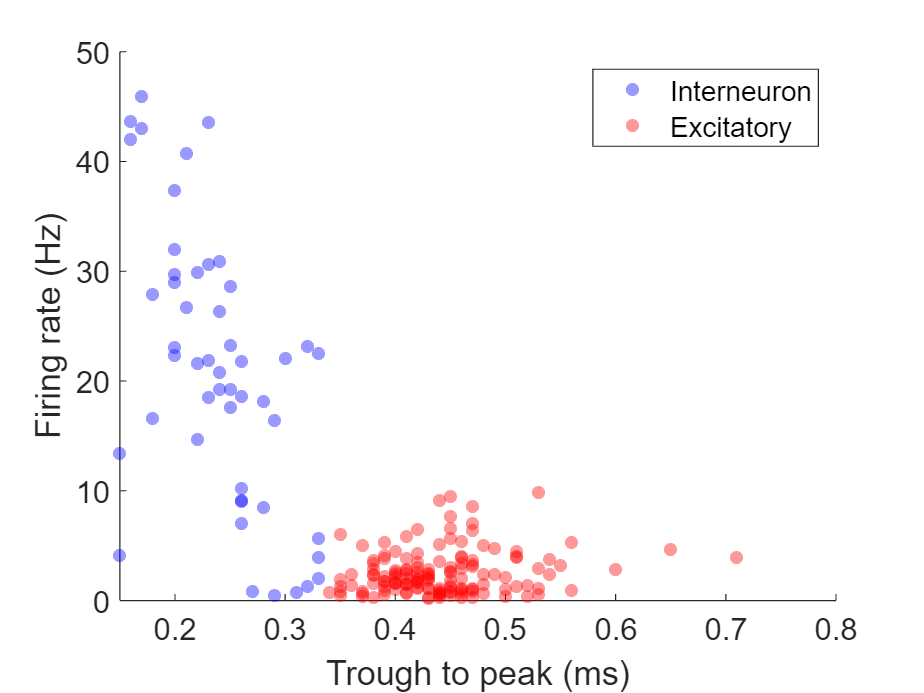

% saveas(fig,fullfile(FigDir,'Trough2Peak_depth.png'))

fig = figure;
hold on
scatter(trough2peak(strcmp(celltype,'Interneuron')),unit_fr(strcmp(celltype,'Interneuron')),'b','filled','o','MarkerFaceAlpha',0.4)
scatter(trough2peak(strcmp(celltype,'Excitatory')),unit_fr(strcmp(celltype,'Excitatory')),'r','filled','o','MarkerFaceAlpha',0.4)
hold off

ylabel('Firing rate (Hz)')
xlabel('Trough to peak (ms)')
legend({'Interneuron','Excitatory'})
set(gca,'FontSize',14)

### Summary of socially modualted neurons

self_land = logical(cell2mat(data_all(:,6)));
self_toff = logical(cell2mat(data_all(:,7)));

other_land = logical(cell2mat(data_all(:,8)));
other_toff = logical(cell2mat(data_all(:,9)));

self_social = self_land | self_toff;
other_social = other_land | other_toff;

is_in = strcmp(celltype,'Interneuron');
is_en = strcmp(celltype,'Excitatory');

n_in = sum(is_in);
n_en = sum(is_en);



fprintf('Interneurons modulated by self action: %.1f%%\n',sum(is_in&self_social)/n_in*100)

Interneurons modulated by self action: 50.0%


fprintf('Excitatory neurons modulated by self action: %.1f%%\n',sum(is_en&self_social)/n_en*100)

Excitatory neurons modulated by self action: 27.0%



fprintf('Interneurons modulated by others'' action: %.1f%%\n',sum(is_in&other_social)/n_in*100)

Interneurons modulated by others' action: 76.0%


fprintf('Excitatory neurons modulated by others'' action: %.1f%%\n',sum(is_en&other_social)/n_en*100)

Excitatory neurons modulated by others' action: 14.9%


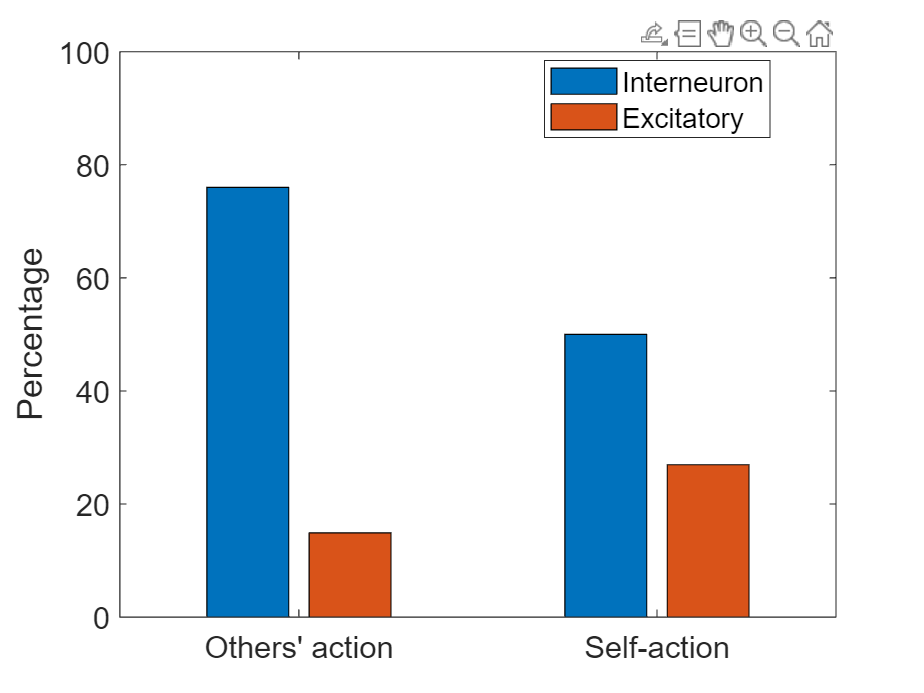

x = categorical({'Self-action','Others'' action'});
y = [sum(is_in&self_social)/n_in*100, sum(is_en&self_social)/n_en*100; sum(is_in&other_social)/n_in*100, sum(is_en&other_social)/n_en*100];
figure
bar(x,y)
ylabel('Percentage')
ylim([0,100])
legend({'Interneuron','Excitatory'},'Location','best')
set(gca,'FontSize',14)